# Using ang-vector technic

## Transformation $A\longrightarrow B\longrightarrow T_B^A$

Two coordinate frames A and B of arbitrary orientation are relatBed by a single rotation about some axis K_hat in space. 

A=eye(3) % The reference frame

A =      1     0     0
     0     1     0
     0     0     1


    trplot(A, ... %We plot the reference frame U with all the options
        'frame', 'A', ... 
        'color', 'g',...
        'arrow',...
        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
        'axis',[-1 1 -1 1 -1 1],...
        'view',[-60,-36],...
        'width', 1.2)
    hold on
    xlabel('X','HorizontalAlignment','left','FontSize',16);
    ylabel('Y','FontSize',16,'HorizontalAlignment','left');
    zlabel('Z','FontSize',16);
% Lets get B
    B=A*eul2r(pi/4,pi/4,pi/2)

B =    -0.7071   -0.5000    0.5000
    0.7071   -0.5000    0.5000
         0    0.7071    0.7071


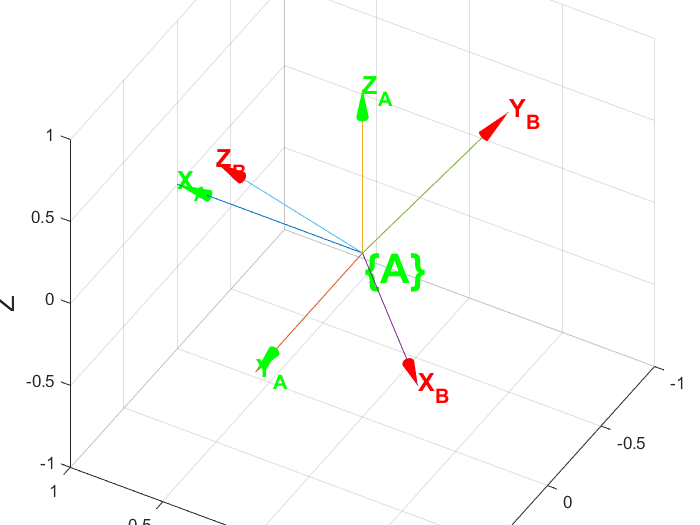

    trplot(B, ... %We plot the frame T 
        'frame', 'B', ... 
        'color', 'r',...
        'arrow',...
        'text_opts', {'FontSize', 15, 'FontWeight', 'bold'},...
        'axis',[-1 1 -1 1 -1 1],...
        'view',[-150,40],...
        'width', 1.2)

    
R_BA=inv(A)*B % Matriz de rotacion B respecto A

R_BA =    -0.7071   -0.5000    0.5000
    0.7071   -0.5000    0.5000
         0    0.7071    0.7071


## Find the angle and vector

[theta, v] = tr2angvec(R_BA) % Metodo 1

theta = 2.4189

v =     0.1566    0.3780    0.9125


SSOO33=SO3(R_BA)    % Metodo 2

 

SSOO33 = 
   -0.7071   -0.5000    0.5000
    0.7071   -0.5000    0.5000
         0    0.7071    0.7071


SSOO33.toangvec(R_BA)

Rotation: 2.418858 rad x [0.156558 0.377964 0.912487]


Q=UnitQuaternion(R_BA) % Metodo 3

 
Q = 
 
0.35355 < 0.14645, 0.35355, 0.85355 >
 


Q.R

ans =    -0.7071   -0.5000    0.5000
    0.7071   -0.5000    0.5000
    0.0000    0.7071    0.7071


## Displaying an animation 

Imagine that rotation matrix C is such that brings z axis of frame A  equal to K_hat axis,  

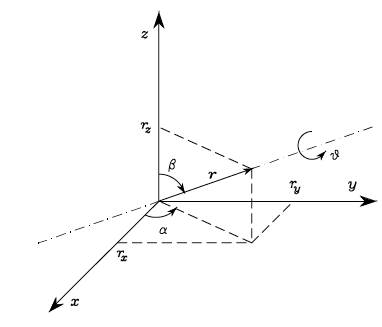

mArrow3([0 0 0],v,'color','blue','stemWidth',0.02,'facealpha',0.5)

ans =   Patch - 属性:

    FaceColor: [0 0 1]
    FaceAlpha: 0.5000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [302×251 double]
     Vertices: [354×3 double]

  显示 所有属性



sin_alpha=v(2)/sqrt(v(1)^2+v(2)^2)

sin_alpha = 0.9239

cos_alpha=v(1)/sqrt(v(1)^2+v(2)^2)

cos_alpha = 0.3827

alpha=atan2(sin_alpha,cos_alpha)

alpha = 1.1781


tranimate(rotz(alpha))

sin_beta=sqrt(v(1)^2+v(2)^2)

sin_beta = 0.4091

cos_beta=v(3)

cos_beta = 0.9125

beta=atan2(sin_beta,cos_beta)

beta = 0.4215


C=rotz(alpha)*roty(beta)% C bring Za  axis same as the vector K_hat 

C =     0.3492   -0.9239    0.1566
    0.8430    0.3827    0.3780
   -0.4091         0    0.9125


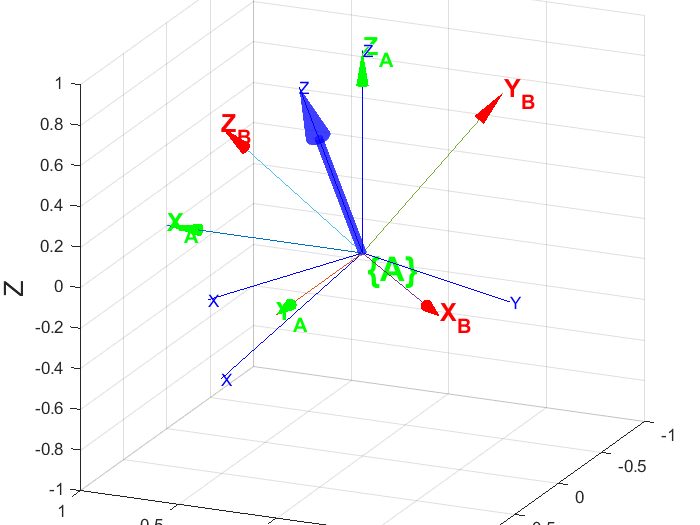


tranimate(rotz(alpha),C,40) 

## Cheking that $\textrm{Av}=v$

The vector v does not change

trot_k_theta=r2t(C)*trotz(theta)*(r2t(inv(C)))

trot_k_theta =    -0.7071   -0.5000    0.5000         0
    0.7071   -0.5000    0.5000         0
    0.0000    0.7071    0.7071         0
         0         0         0    1.0000


v_n=trot_k_theta*[v 1]'

v_n =     0.1566
    0.3780
    0.9125
    1.0000


v

v =     0.1566    0.3780    0.9125


##  Aplying theory to get back v an theta

CC=trot_k_theta

CC =    -0.7071   -0.5000    0.5000         0
    0.7071   -0.5000    0.5000         0
    0.0000    0.7071    0.7071         0
         0         0         0    1.0000



theta= acos((CC(1,1)+CC(2,2)+CC(3,3)-1)/2);
sin_theta=(sqrt((CC(3,2)-CC(2,3))^2+(CC(1,3)-CC(3,1))^2+(CC(2,1)-CC(1,2))^2))/2;
v_x=(CC(3,2)-CC(2,3))/(2*sin_theta);
v_y=(CC(1,3)-CC(3,1))/(2*sin_theta);
v_z=(CC(2,1)-CC(1,2))/(2*sin_theta);
v_the=[v_x v_y v_z]

v_the =     0.1566    0.3780    0.9125


## Using the RTB function

[theta, v] = tr2angvec(CC)

theta = 2.4189

v =     0.1566    0.3780    0.9125


## Using Matlab eig command

[v_eig,lambda] = eig(CC)

v_eig =    0.6984 + 0.0000i   0.6984 + 0.0000i   0.1566 + 0.0000i   0.0000 + 0.0000i
  -0.0424 - 0.6533i  -0.0424 + 0.6533i   0.3780 + 0.0000i   0.0000 + 0.0000i
  -0.1023 + 0.2706i  -0.1023 - 0.2706i   0.9125 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i


lambda =   -0.7500 + 0.6614i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.7500 - 0.6614i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i


vector=v_eig*[0 0 1 1]'

vector =     0.1566
    0.3780
    0.9125
    1.0000



rotation=angle(lambda(1,1))% returns the phase of the complex number

rotation = 2.4189

% rotation = 1.2344

